clc; clear; close all;

# Given Data

We assume we are given points on the boundary and points on a cartesian mesh on the interior

phi = @(x, y) exp(2*x.^2 + y.^2);

% spacing between cartesian mesh points
k_grid = 0.01;

% spacing for parameterization of boundary
k_theta = 0.01;

% Gamma (boundary)
theta = 0:k_theta:2*pi; % parameterized grid
r = 1; % radius of circle
x_Gamma = cos(theta);
y_Gamma = sin(theta);
phi_Gamma = phi(x_Gamma, y_Gamma)

phi_Gamma =      7.389056098930650e+00     7.388317254892201e+00     7.386101461441149e+00     7.382410933123273e+00     7.377249356029187e+00     7.370621880582014e+00     7.362535111472415e+00     7.352997094773165e+00     7.342017302274291e+00     7.329606613088555e+00     7.315777292585684e+00     7.300542968721797e+00     7.283918605838568e+00     7.265920476014264e+00     7.246566128055960e+00     7.225874354229099e+00     7.203865154827024e+00     7.180559700688980e+00     7.155980293780627e+00     7.130150325956103e+00     7.103094236025035e+00     7.074837465251978e+00     7.045406411419102e+00     7.014828381585808e+00     6.983131543681246e+00     6.950344877067539e+00     6.916498122212639e+00     6.881621729612414e+00     6.845746808101728e+00     6.808905072693824e+00     6.771128792086331e+00     6.732450735970896e+00     6.692904122281363e+00     6.652522564513153e+00     6.611340019243509e+00     6.569390733979168e+00     6.526709195454114e+00     6.483330078496257e+00


% Omega (interior)
% I will construct a square grid, 
% but only points within boundary are given
[x_Omega, y_Omega] = meshgrid(-1:k_grid:1);
interior_msk = x_Omega.^2 + y_Omega.^2 < 1;
x_Omega = x_Omega(interior_msk)

x_Omega =     -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01
    -9.900000000000000e-01


y_Omega = y_Omega(interior_msk)

y_Omega =     -1.400000000000000e-01
    -1.300000000000000e-01
    -1.200000000000000e-01
    -1.100000000000000e-01
    -9.999999999999998e-02
    -8.999999999999997e-02
    -7.999999999999996e-02
    -6.999999999999995e-02
    -5.999999999999994e-02
    -4.999999999999993e-02


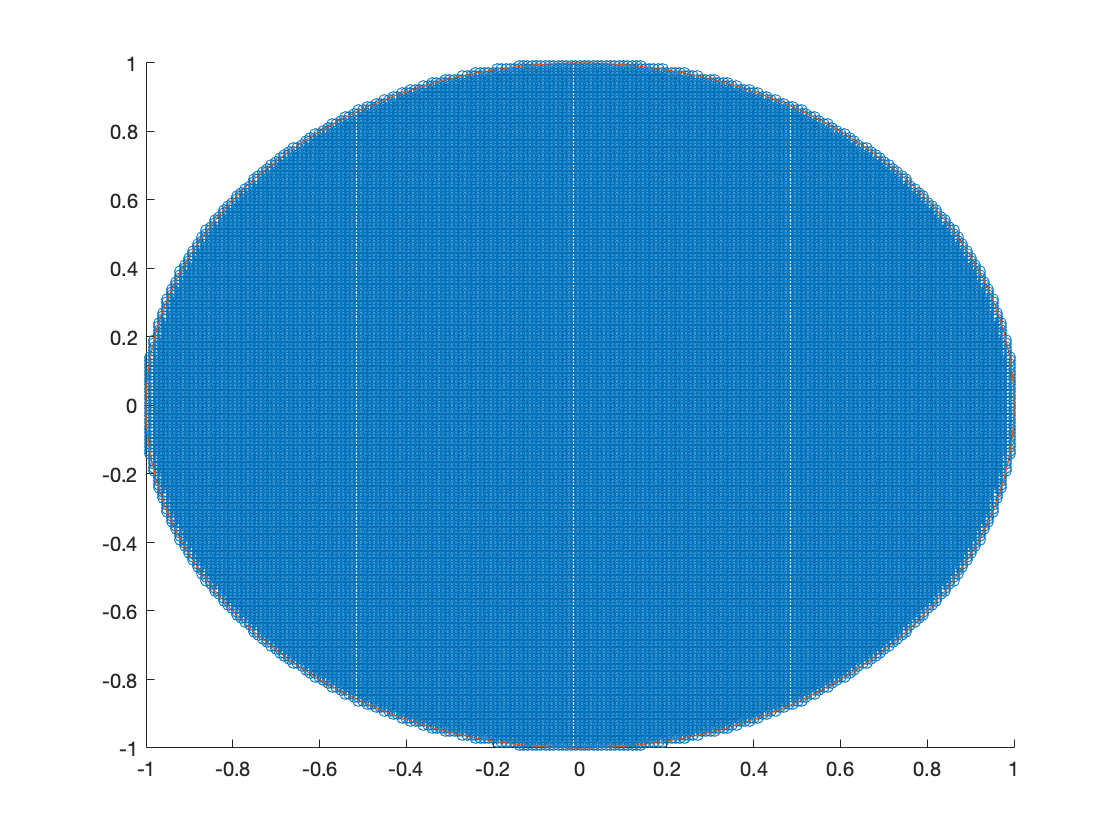


figure;
hold on;
scatter3(x_Omega, y_Omega, phi(x_Omega, y_Omega))
plot3(x_Gamma, y_Gamma, phi(x_Gamma, y_Gamma))